load ifk.mat

### N01. Discretize the integral equation using simple collocation to create a square G matrix

[m,n] = size(d);
a = 0; b = 1;

n = m;

dx = (b-a)/m

dx = 0.0500

g = @(x,y) x*exp(-x*y)

g = function_handle with value:
    @(x,y)x*exp(-x*y)


x = [];
for j = 1:n
    x = [x  a + (dx/2) + (j-1)*dx]; %form x
end
y = x;

G = zeros(m,n);
for i = 1:m
    for j = 1:n
        G(i,j) = g(x(j),y(i)).*dx; %form G
    end
end
G

G =     0.0012    0.0037    0.0062    0.0087    0.0112    0.0137    0.0161    0.0186    0.0210    0.0235    0.0259    0.0283    0.0308    0.0332    0.0356    0.0380    0.0404    0.0428    0.0452    0.0476
    0.0012    0.0037    0.0062    0.0086    0.0111    0.0135    0.0159    0.0182    0.0206    0.0229    0.0252    0.0275    0.0298    0.0321    0.0343    0.0366    0.0388    0.0410    0.0432    0.0453
    0.0012    0.0037    0.0062    0.0086    0.0109    0.0133    0.0156    0.0179    0.0202    0.0224    0.0246    0.0268    0.0289    0.0310    0.0331    0.0352    0.0372    0.0392    0.0412    0.0432
    0.0012    0.0037    0.0061    0.0085    0.0108    0.0131    0.0154    0.0176    0.0197    0.0219    0.0239    0.0260    0.0280    0.0300    0.0319    0.0338    0.0357    0.0375    0.0393    0.0411
    0.0012    0.0037    0.0061    0.0084    0.0107    0.0129    0.0151    0.0172    0.0193    0.0213    0.0233    0.0253    0.0272    0.0290    0.0308    0.0325    0.0343    0.0359    0.0376  

### Plot the singular values, and $1/j^{\alpha}$ for well chosen values of α on the same graph.

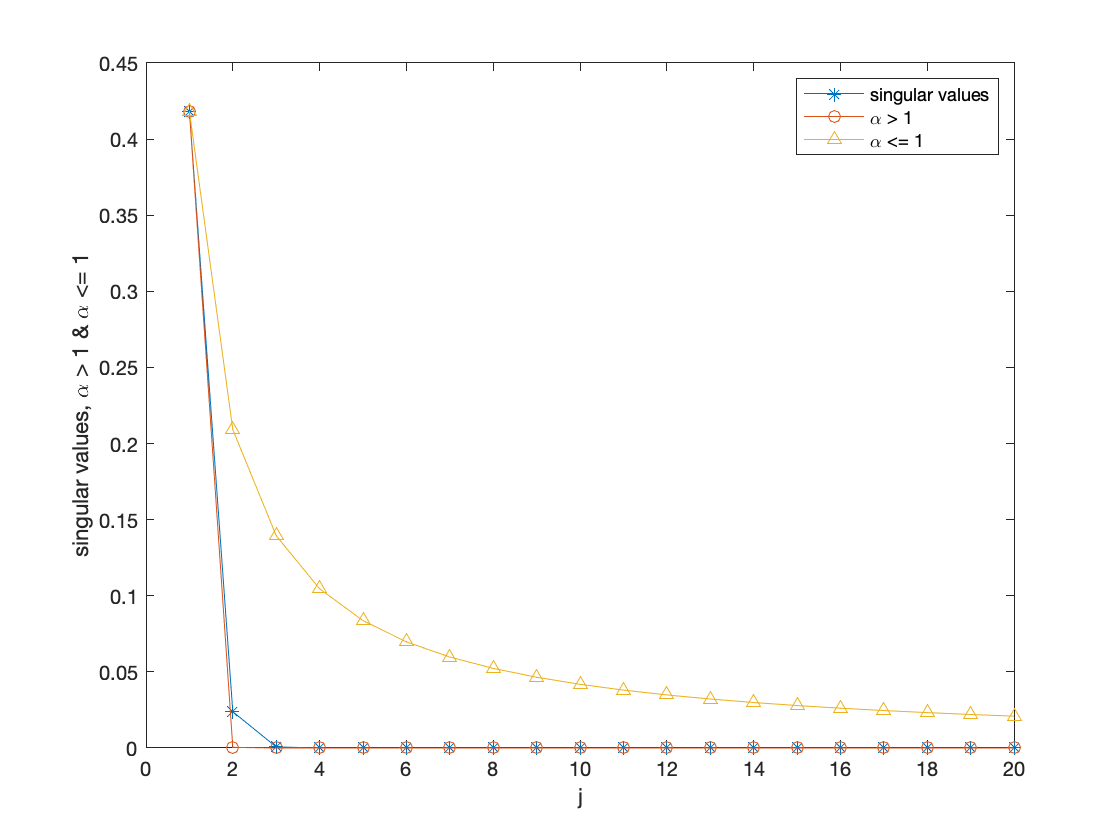

% Get the singular values for the system matrix
[U,S,V] = svd(G);

j = linspace(1,m,m);
c = S(1,1);
alpha1 = 10;
alpha2 = 1;
alpha_g1 =  c./(j.^alpha1); %alpha greater than 1
alpha_l1 = c./(j.^alpha2);  %alpha less or equal 1

figure(1)
plot(diag(S),'-*'); hold on
plot(alpha_g1,'-o'); hold on
plot(alpha_l1,'-^')
legend('singular values','\alpha > 1','\alpha <= 1')
ylabel('singular values, \alpha > 1 & \alpha <= 1'); xlabel('j')

### Discuss if this problem is mildly or moderately ill-posed.

According to the graph above, the problem is moderately ill-posed since $s_{j}  = O\left(\frac{1}{j^{\alpha}}\right)$ for $\alpha > 1$

### N0.2 Plot the log of the singular values and identify a value for i above which the singular values can reasonably be considered to be nonzero, and below which the singular values can be considered to be zero.

i = 9

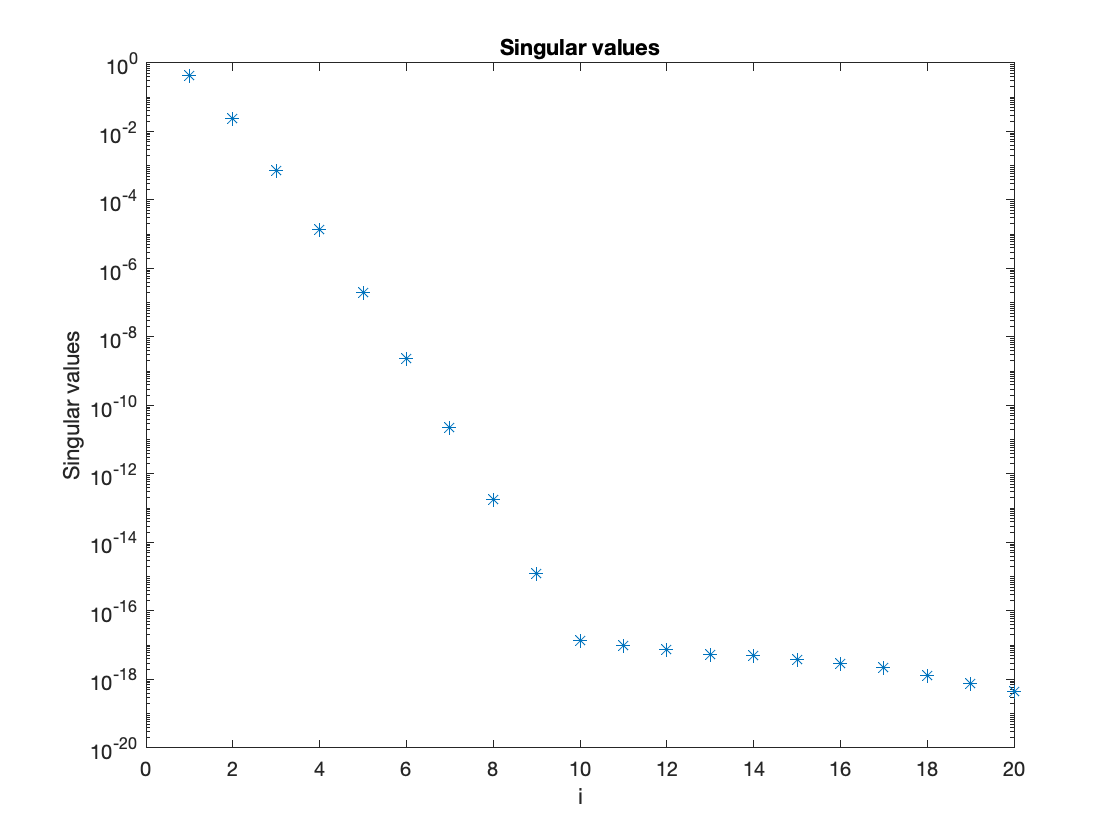

figure(2)
semilogy(diag(S),'*')
title('Singular values')
xlabel("i"); ylabel('Singular values')

### N0.3 Plot the log of the magnitude of the Picard ratios UT:,id/si.

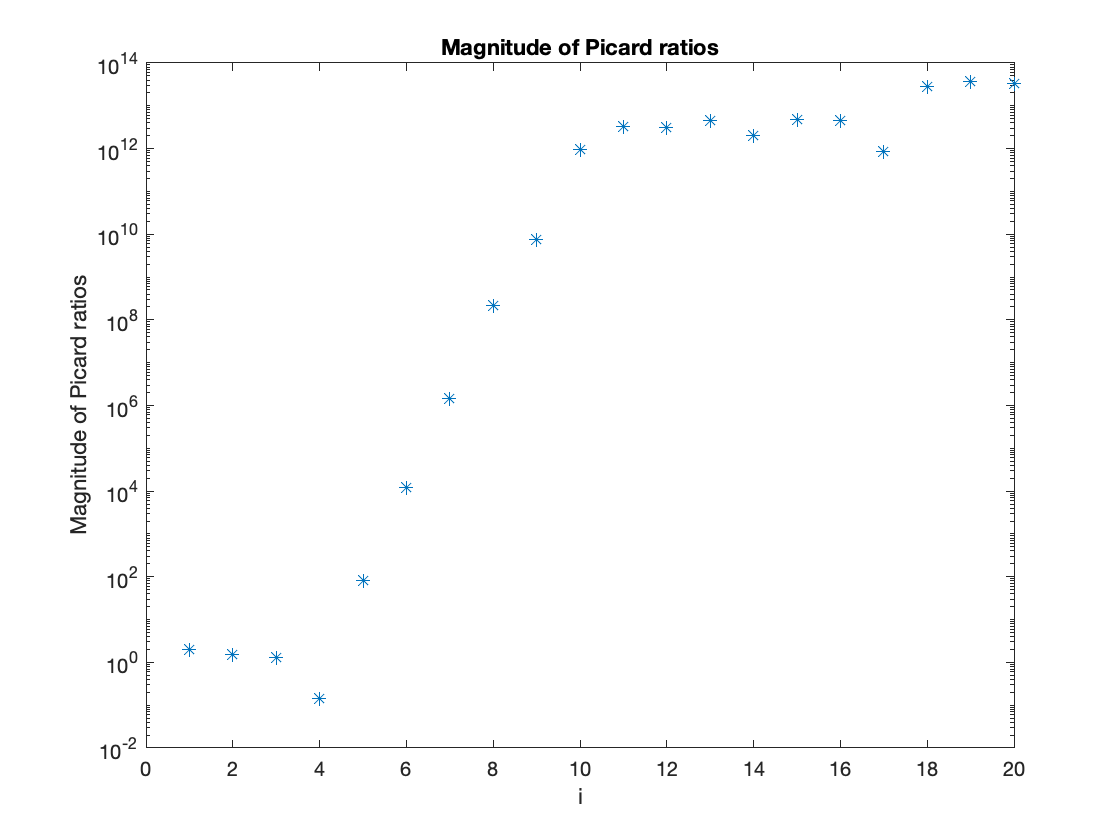

% Picard's ratios
Si = diag(S);
Picard = [];
for i = 1:m
    Picard = [Picard abs((U(:,i)'*d)/Si(i))];
end
figure(3)
semilogy(Picard,'*')
ylabel('Magnitude of Picard ratios'); xlabel('i');
title('Magnitude of Picard ratios');

### Identify a value for i where these coefficients abruptly increase. 

i = 5

### Compare this to the value for i you identified in 2.

This  value of i is smaller than that identified in 2.

### N04. Use equation (3.80) to produce truncated SVD (TSVD) model parameter estimates

i = 4;
mdagger = 0;
for j = 1:i
    mdagger = mdagger + (U(:,j)'*d/Si(j))*V(:,j);
end
mdagger

mdagger =     0.2411
    0.6060
    0.8390
    0.9664
    1.0114
    0.9942
    0.9327
    0.8420
    0.7353
    0.6236


### Use trial and error to choose the largest possible i so that you get a reasonable looking graph.

i = 4

i = 4

### Compare this value of i to those you identified in 3 and 2.

The value of i is less than the values of i identified in 3 and 4. 

### Plot the best looking estimates.

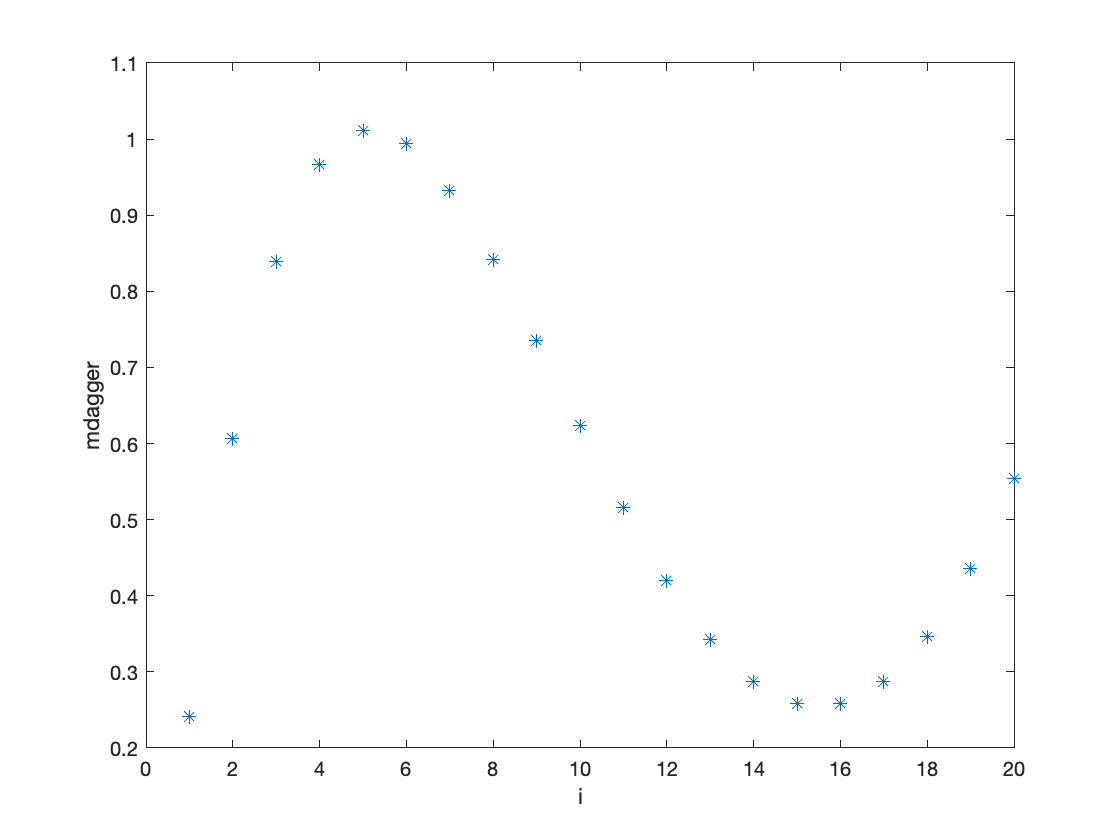

figure(4)
plot(mdagger,'*')
ylabel('mdagger'); xlabel('i')

### N0.5 Plot the true parameters along with your best estimate from 4. On the same graph, also plot a TSVD estimate created by truncating at i −1 singular values, where i gave you the best TSVD estimate.

mtrue = @(x) exp(-10*(x-0.2).^2) + 0.4*exp(-10*(x-0.9).^2) 

mtrue = function_handle with value:
    @(x)exp(-10*(x-0.2).^2)+0.4*exp(-10*(x-0.9).^2)


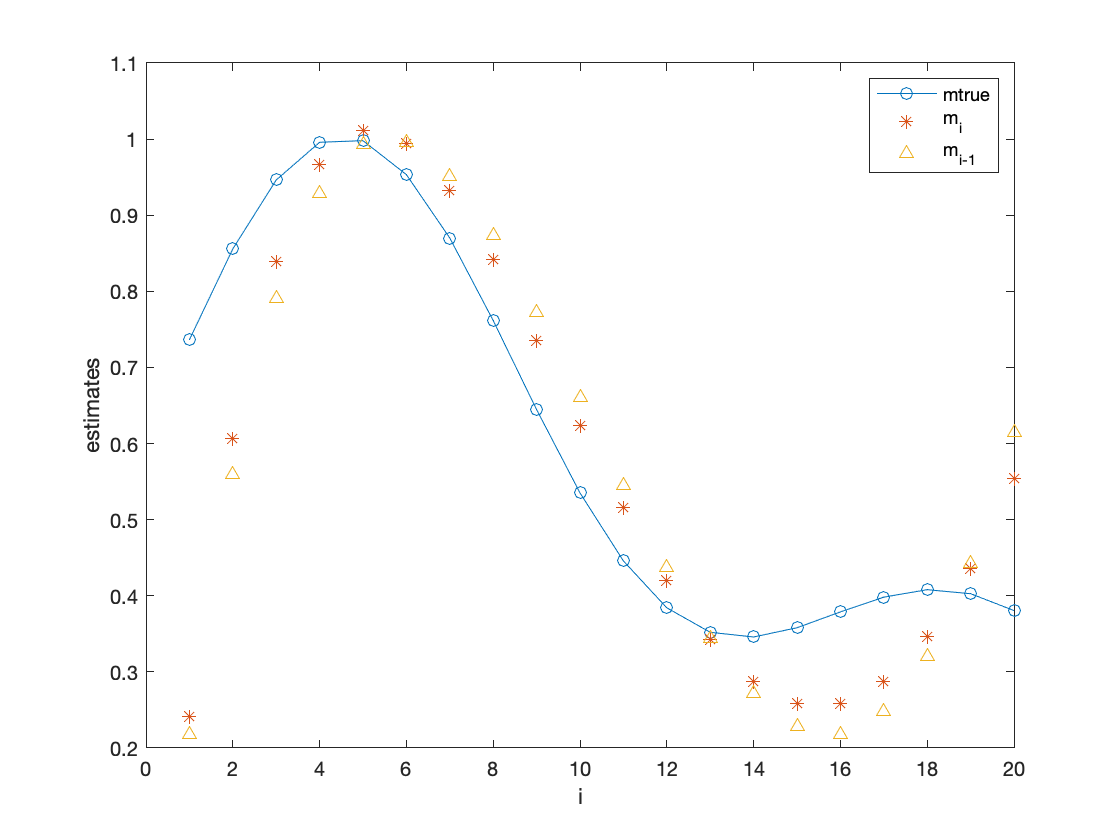

%TSVD estimate 
i = 4;
Si = Si(1:i-1);
mest = 0;
for j = 1:i-1
    mest = mest + (U(:,j)'*d/Si(j))*V(:,j);
end
mest;

figure(5)
plot(mtrue(x),'-o'); hold on
plot(mdagger,'*'); hold on
plot(mest,'^')
xlabel('i'); ylabel('estimates')

legend('mtrue','m_{i}','m_{i-1}')

### Discuss how well your TSVD model parameters estimated the true parameters.

 The TSVD model parameters are out of phase from the true model parameters as depicted in the curve, however at certain peaks i.e $$i=5$ $and $i=13$, the TSVD parameters fit the true model parameters. Also the further we truncate, the further we get away from the true solution as we see that $m_{i}$ is better than $m_{i-1}$.